**Path Planning**

Set the start and goal pose

% Define Start and Goal Pose
pose_origin = [0 0 0];
pose_1 = [25.8 -4.27 0];
pose_2 = [14 10 pi/3];
pose_3 = [-10.9 1.4 pi/3];

start = pose_origin;
goal = pose_1;

Define the maximum incline angle and convert it to slope

maxinclineangle = 5; % Degrees
maxSlope = tand(maxinclineangle); % Max preferred slope for vehicle

Constuct Z-layer

% Query and store the Z-height
zLayer = mapLayer(flipud(Z),LayerName="Z",Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);

Calculate the gradient and convert to cost

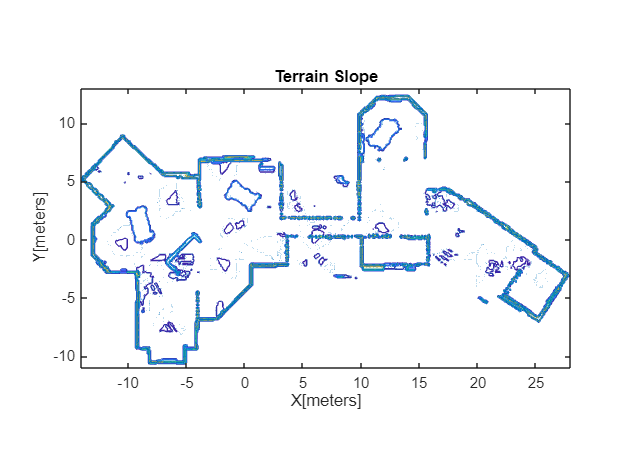

[gx,gy] = gradient(Z);
figure
contour(X,Y,Z)
title("Terrain Slope")
xlabel('X[meters]')
ylabel('Y[meters]') 
hold on
quiver(X,Y,gx,gy)
axis equal
hold off

Store the gradients

dzdx = mapLayer(flipud(gx),LayerName="dzdx", Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);
dzdy = mapLayer(flipud(gy),LayerName="dzdy", Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);

Calculate the cost and slope

addpath("MapProcessing");
slope2cost = @(x)exampleHelperGradientToCost(maxSlope,flipud(x));
slope = linspace(-2*maxSlope,2*maxSlope,100);
% plot(slope,slope2cost(slope))
% hold on
% xline(maxSlope*[-1 1],"r:")
% yline(1,"b:")
% title("Cost vs Slope")
% xlabel("Slope")
% ylabel("Cost")
% axis square

Calculate costs using the slope function, and store them in map layers.

xCost = mapLayer(slope2cost(gx),LayerName="xCost", Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);
yCost = mapLayer(slope2cost(gy),LayerName="yCost", Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);
diagCost = mapLayer(slope2cost(sqrt(gx.^2+gy.^2)),LayerName="diagCost", Resolution=1/step_size, GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0, 0]);

**Terrain Obstacles**

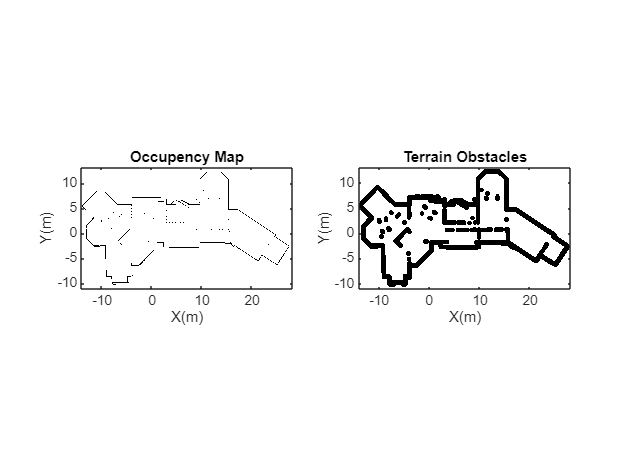

% Initialise obstacle probabilities
% obstacleprob = zeros(y_len, x_len);
occupancy_image = imread('occupency_map.pgm');
imageCropped = occupancy_image(1760-15:2241-15,1580+145:2421+145);
imageCropped = imresize(imageCropped, [241, 421]);
imageNorm = double(imageCropped)/255;
imageOccupancy = 1 - imageNorm;
obstacleprob = imageOccupancy;
% Create the binary occupancy map for obstacles
obstacleMap = binaryOccupancyMap(obstacleprob > 0.4, 1/step_size, LayerName="obstacles", GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0,  0]); 

% Create the terrain obstacles map without including obstacleMap
terrainObstacles = binaryOccupancyMap(obstacleMap, LayerName="terrainObstacles", GridOriginInLocal=[x_offset, y_offset], LocalOriginInWorld=[0,  0]);

% Inflate the terrain obstacles map
inflate(terrainObstacles, 0.35); % The Husky Robot is 0.67m wide

% Extract map data
obstaclesAndTerrain = double(getMapData(terrainObstacles));

% Slope constraints checking (assuming xCost, yCost, diagCost are defined)
% mInvalidSlope = <your slope constraints logic here>;

% Calculate cells that violate all three slope constraints
mInvalidSlope = xCost > 0.1 & yCost > 0.1 & diagCost > 0.1;

% Block off cells that violate all three slope constraints in the terrain map
obstaclesAndTerrain(mInvalidSlope) = true;

% % Ensure the original obstacles are not included in the terrain map
% originalObstacles = getMapData(obstacleMap);
% obstaclesAndTerrain(originalObstacles) = false;

% Update the terrainObstacles map with the new data
setMapData(terrainObstacles, obstaclesAndTerrain);

% Display the obstacles
figure;
show(obstacleMap,Parent=subplot(1,2,1));
title("Occupency Map");
xlabel('X(m)');
ylabel('Y(m)'); 
show(terrainObstacles,Parent=subplot(1,2,2));
title("Terrain Obstacles");
xlabel('X(m)');
ylabel('Y(m)'); 

**Combine Individual Map Layers**

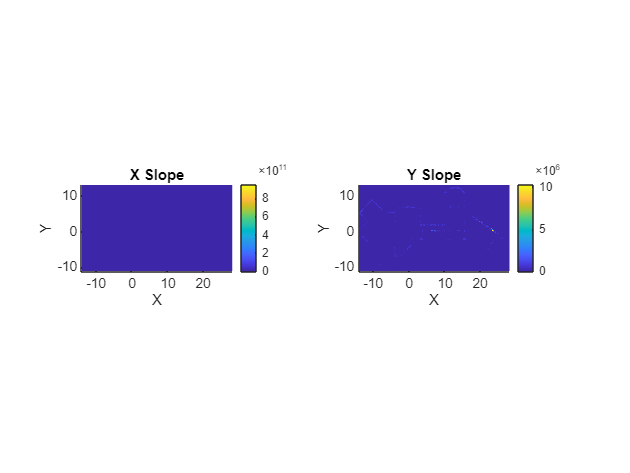

costMap = multiLayerMap({zLayer dzdx dzdy terrainObstacles xCost yCost diagCost});
xCost.GridOriginInLocal = -xCost.GridSize/xCost.Resolution/2;
% Restore map to original settings
costMap.GridOriginInLocal = [x_offset y_offset];

% Add helper folders to path
addpath("Analysis");
figure;
show(visualizationHelper,xCost,subplot(1,2,1),hold="on",title="X Slope");
xlabel('X');
ylabel('Y'); 
show(visualizationHelper,yCost,subplot(1,2,2),hold="on",title="Y Slope");
xlabel('X');
ylabel('Y');

**Plan Paths Using 2.5-D Heuristics**

plannerType = "plannerAStarGrid"; % plannerAStarGrid plannerHybridAStar

% If the planner type is plannerAStarGrid, convert the start and goal locations to grid coordinates.
if strcmp(plannerType,"plannerAStarGrid")
    start = world2grid(costMap,start(:,1:2));
    goal  = world2grid(costMap,goal(:,1:2));
end

gWeight = 1;
hWeight = 1;
addpath("Heuristics");
[defaultPlanner,heightAwarePlanner,gradientAwarePlanner,rolloverAwarePlanner] = exampleHelperCreatePlannerObject(plannerType,costMap,gWeight,hWeight);

% Planners return a sequence of IJ cells
paths = cell(4,1);
planningTime = nan(4,1);
tic;
paths{1} = plan(defaultPlanner,start,goal);
planningTime(1) = toc;
paths{2} = plan(heightAwarePlanner,start,goal); 
planningTime(2) = toc-planningTime(1);
paths{3} = plan(gradientAwarePlanner,start,goal); % slope along the path
planningTime(3) = toc-planningTime(2);
paths{4} = plan(rolloverAwarePlanner,start,goal); % slope perpendicular to the path
planningTime(4) = toc-planningTime(3);

if strcmp(plannerType,"plannerHybridAStar")
    for i=1:4
        paths{i} = paths{i}.States;
    end
end

**Define Robot and Scenario Parameters**

% Define simulation parameters
scenarioParams.Gravity = 9.81; % m/s^2
scenarioParams.UpdateRate = 1/60; % Hz

% Define vehicle parameters for estimating power consumption
scenarioParams.Robot.Mass = 70 % kg, no payload

scenarioParams = struct with fields:
       Gravity: 9.8100
    UpdateRate: 0.0167
         Robot: [1×1 struct]


scenarioParams.Robot.Velocity = 0.6; % m/s
scenarioParams.Robot.AmpHour = 24;   % A-hr
scenarioParams.Robot.Vnom = 24;      % V, Voltage
scenarioParams.Robot.RegenerativeBrakeEfficiency = 0;

**Define Performance Metrics**

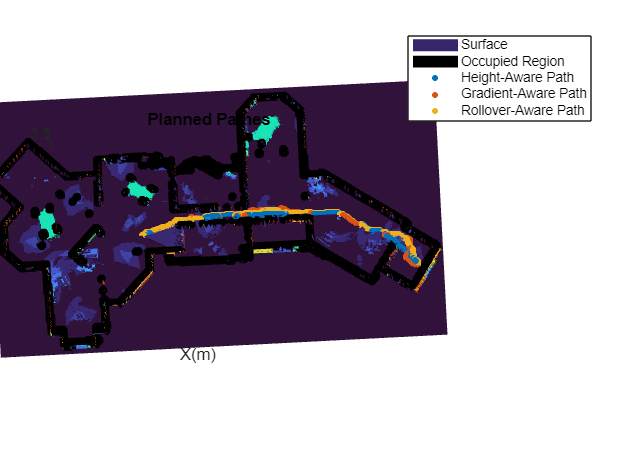

% Display result
figure
animateResults = true;
pathNames = ["Default","Elevation-Aware Path","Gradient-Aware Path","Rollover-Aware Path"];
addpath("Analysis");
statTable = exampleHelperCalculateMetrics(costMap,scenarioParams,paths,planningTime,pathNames,plannerType);
only_gradient = false; % true / false : Whether only show "Gradient-Aware" path
if(only_gradient)
    paths_selected = paths(3);
    pathNames_selected = "Gradient-Aware Path";
else
    paths_selected = paths(2:4);
    pathNames_selected = ["Height-Aware Path", "Gradient-Aware Path","Rollover-Aware Path"];
end
exampleHelperVisualizeResults(gca,statTable,scenarioParams,costMap,paths_selected,pathNames_selected,~animateResults,plannerType);
title("Planned Pathes")
xlabel('X(m)')
ylabel('Y(m)') 

**Apply offset and save the paths**

% If the planner type is plannerAStarGrid, convert the start and goal locations to grid coordinates.
if strcmp(plannerType,"plannerAStarGrid")
    for i = 1:length(paths)
        paths{i} = grid2world(costMap, paths{i}); % Convert each path to world coordinates
    end
end


paths_offset = paths;


% for Simulink control model
% set_param('controlling/Inputs/Waypoints Input', 'Value', 'paths_offset{2}');